clear; clc; close all;

split_idx = 5000;
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

% Y_Train = categorical(Y_Train);
% Y_Test = categorical(Y_Test);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [56×5000 double]
      Labels: [4096×5000 double]


dsTest =   MyDataStore with properties:

    Features: [56×1000 double]
      Labels: [4096×1000 double]


layers = [
    featureInputLayer(56, "Normalization", "none")
    fullyConnectedLayer(4032)
    reluLayer
    dropoutLayer(0.95)
    fullyConnectedLayer(4032)
    reluLayer
    dropoutLayer(0.95)
    fullyConnectedLayer(4096)
    regressionLayer
    ]

layers =   9×1 Layer array with layers:

     1   ''   Feature Input       56 features
     2   ''   Fully Connected     4032 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Dropout             95% dropout
     5   ''   Fully Connected     4032 fully connected layer
     6   ''   ReLU                ReLU
     7   ''   Dropout             95% dropout
     8   ''   Fully Connected     4096 fully connected layer
     9   ''   Regression Output   mean-squared-error

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 1000, ...
    'MiniBatchSize', 640, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 1000
                   MiniBatchSize: 640
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnviro

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       122.41 |       7491.8 |          0.0100 |
|       8 |          50 |       00:00:45 |        70.78 |       2505.2 |          0.0100 |
|      10 |          69 |       00:01:01 |        66.08 |       2183.3 |          0.0100 |
|========================================================================================|
Training finished: Stopped manually.


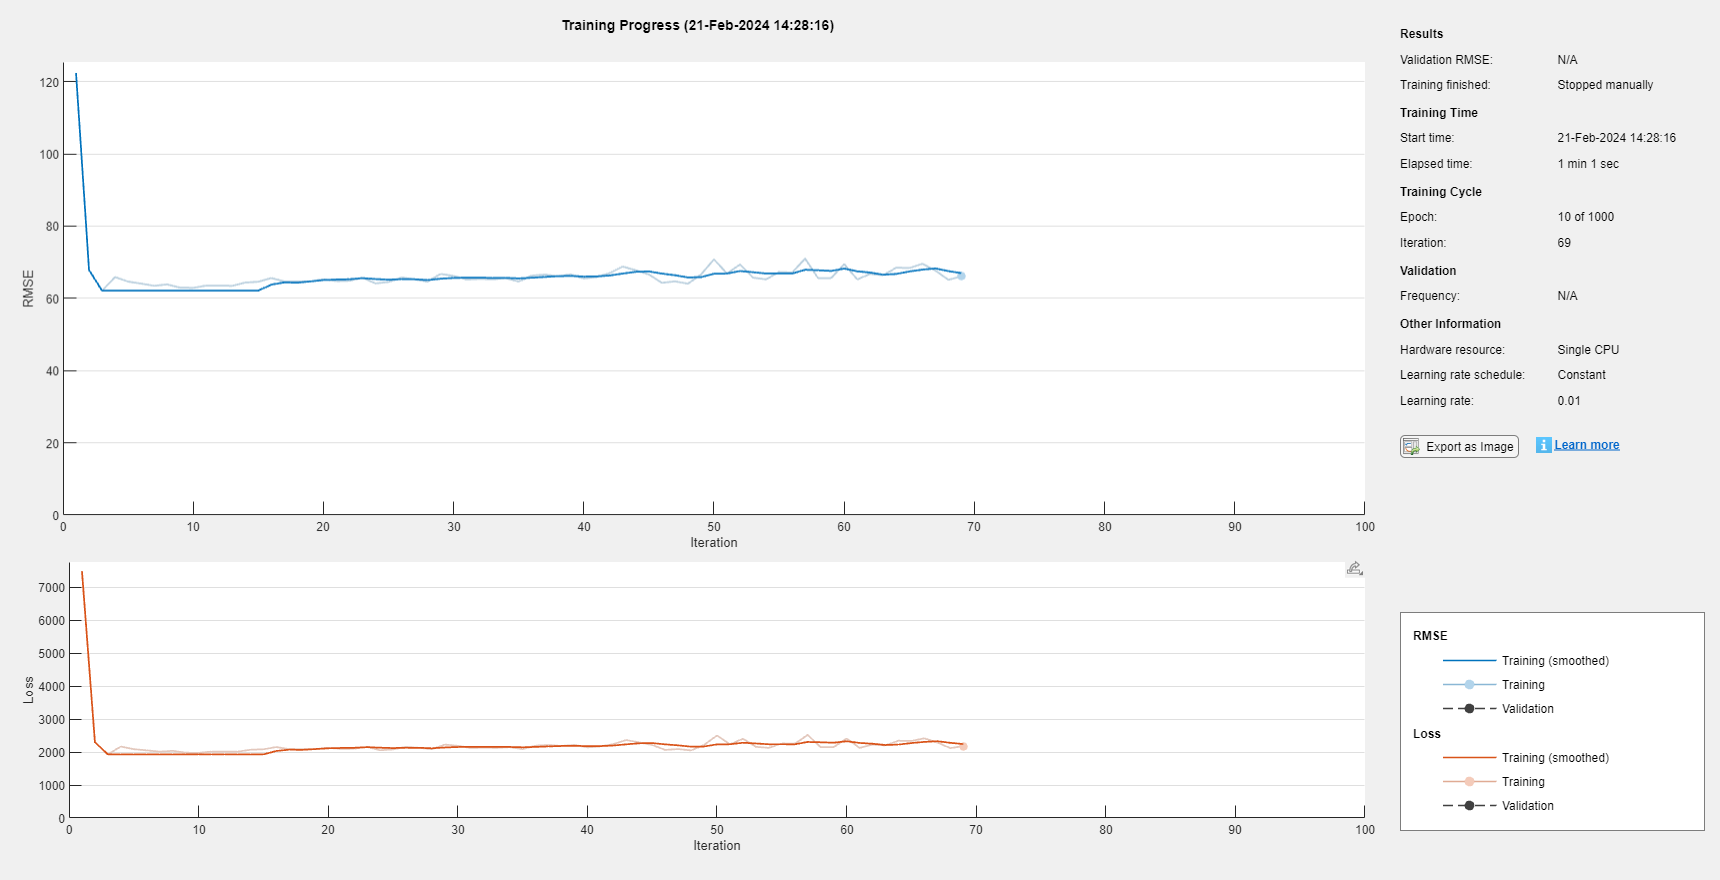

net =   SeriesNetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

r_learned = predict(net, X_Test(:, end).').';

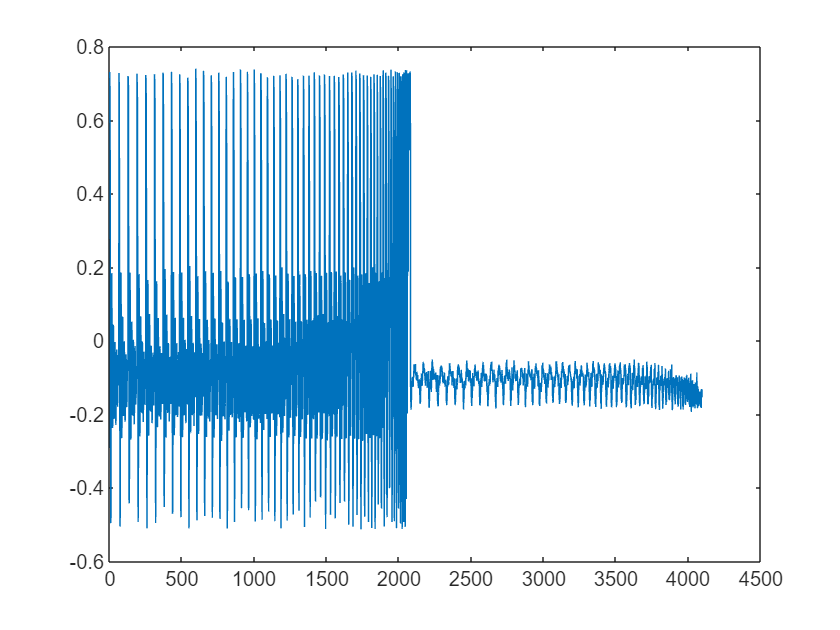

figure;
plot(r_learned);

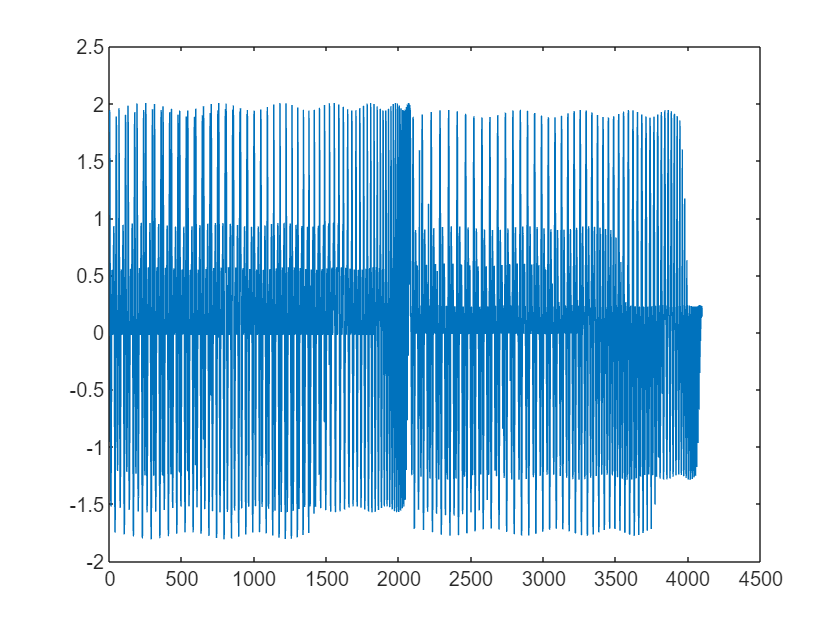

figure;
plot(Y_Test(:, end));

dsTrain.read()

ans = 1×2 cell array
    {4032×1 double}    {[5]}


YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred==YValidation)/numel(YValidation)

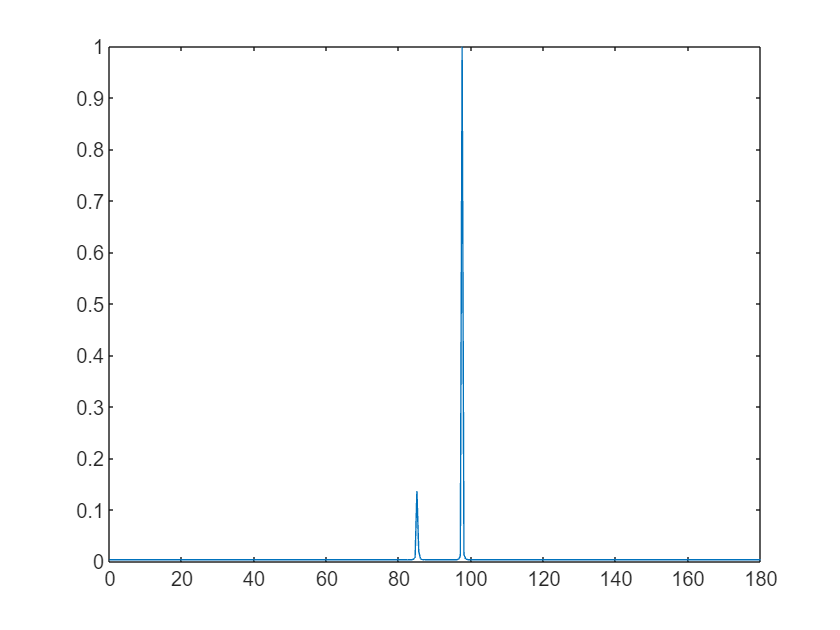

R = r2R(r);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

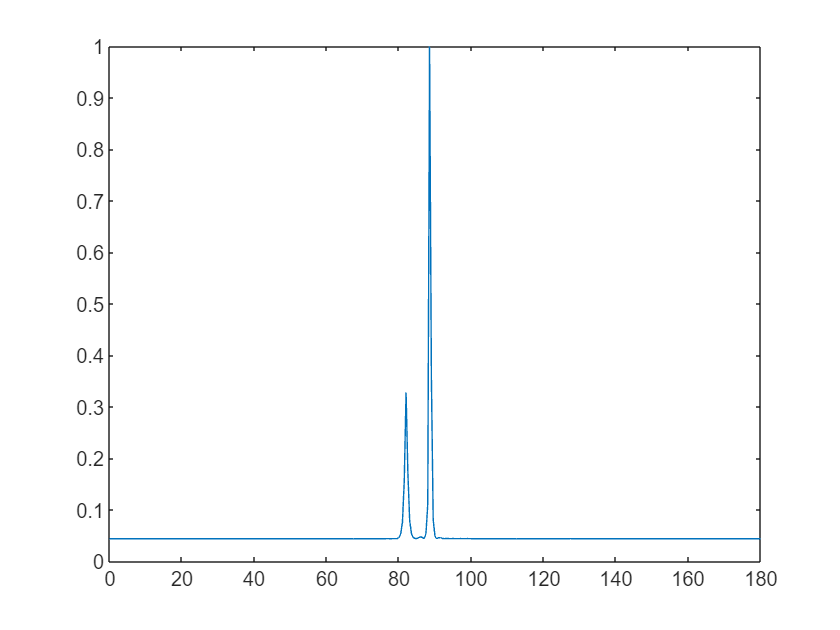

R = r2R(r_learned);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

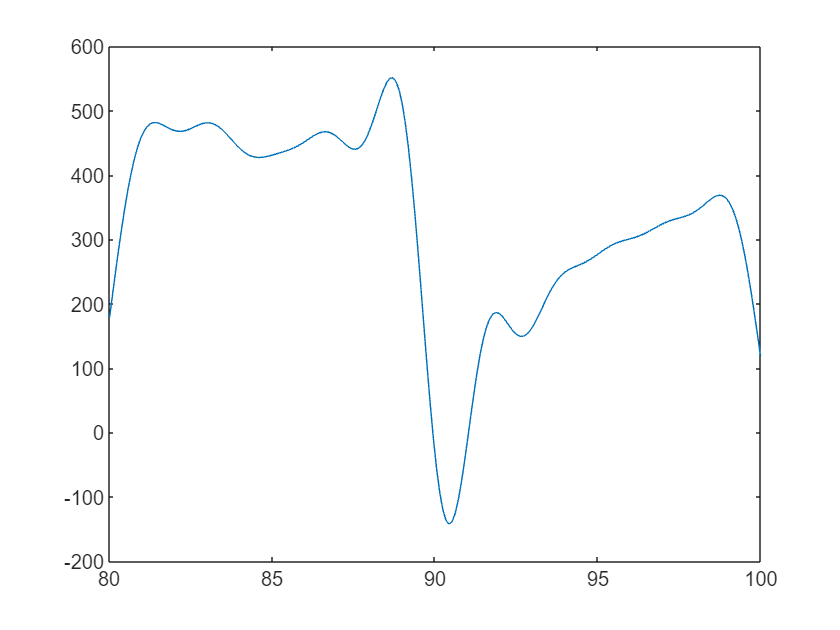

possible_angles = linspace(80, 100, 210);
P = length(possible_angles);
A_star = zeros(M2, P);
for p = 1:P
    A_star(:, p) = exp(1i * pi * (sensor_locations).' * cosd(possible_angles(p)));
end
A_tilda = DOA.khatri_rao(conj(A_star), A_star);

c = R(:);

ksa = A_tilda' * c;
figure;
plot(possible_angles, ksa);

function R = r2R(r)
vecSize = length(r);
% M = sqrt(vecSize + 0.25) + 0.5;
M = sqrt(vecSize);
split_idx = (M+1)*M/2; 
re_r = r(1:split_idx);
im_r = r(split_idx+1:end);
split_idx = 0;
for i = M:-1:1
    im_r = [im_r(1:split_idx); 0; im_r(split_idx+1:end)];
    split_idx = split_idx + i;
end
r2 = re_r + 1i * im_r;
R = zeros(M);
for i = 1:M
    split_idx = M-i+1;
    R(i, i:M) = r2(1:split_idx);
    r2 = r2(split_idx+1:end);
end
R = R + R';
for i = 1:M
    R(i, i) = R(i, i) / 2;
end
end